% importGifPath = '/Users/pho/Desktop/Screencaps/Movies/4a-036.gif';

importGifPath = '/Users/pho/Desktop/Screencaps/Movies/4a-MinProp.gif';
[parentPath, baseName, ext] = fileparts(importGifPath);

outputDir = '/Users/pho/Desktop/Screencaps/Movies/Flattened';
outputName = fullfile(outputDir, [baseName '.png']);

% importPath = '/Users/pho/Desktop/Screencaps/Movies/4c-2000.png';


% Import the file
% [activeGif.cdata, activeGif.colormap, activeGif.alphamap] = imread(importGifPath);

% [activeAnimatedImage.cdata, activeAnimatedImage.colormap, activeAnimatedImage.alphamap] = imread(importPath,'Frames','all');

% [activeAnimatedImage.cdata] = imread(importPath);


[activeGif.cdata] = gifread(importGifPath);
% [activeGif.cdata, activeGif.colormap] = gifread(importGifPath,'indexed');

% [activeGif.cdata, activeGif.colormap] = gifread(importGifPath,'rgb');

% Get the number of frames in the animated gif
numberOfFrames = size(activeGif.cdata,4);

if numberOfFrames < 1
	error('no frames!')
end


activeFrameIndex =4

activeFrameIndex =      4

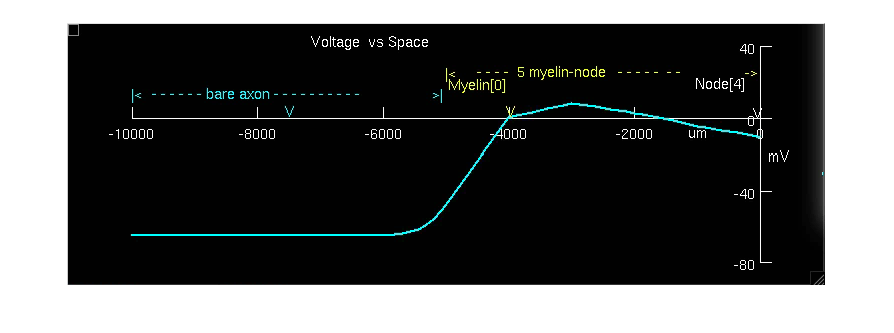

currFrame = imcomplement(activeGif.cdata(:,:,:,activeFrameIndex));


figure(1)
clf
% imshow(currFrame)
imshow(currFrame)

%imshow(currFrame, activeGif.colormap)


% Extract the teal lines:
% currFrame = currFrame(:,:,3);
% Binarize the image:
[fixedImage, excludedPixelsMask] = removeWhiteAxes(currFrame);
dataLineOnlyMask = ~excludedPixelsMask;

axesOnlyImage = currFrame;
% axesOnlyImage(dataLineOnlyMask,1) = 0;
axesOnlyImage(dataLineOnlyMask) = 0;

Unable to perform assignment because the left and right sides have a different number of elements.


imshow(axesOnlyImage)

fixedImage_grey = rgb2gray(fixedImage);
fixedImage_BW = imbinarize(fixedImage_grey);

figure(2)
clf
% imshow(fixedImage)
% imshow(fixedImage_BW)
imshow(dataLineOnlyMask)

imshow(fixedImage_BW)


activeSecondFrameIndex =5

activeSecondFrameIndex =      5

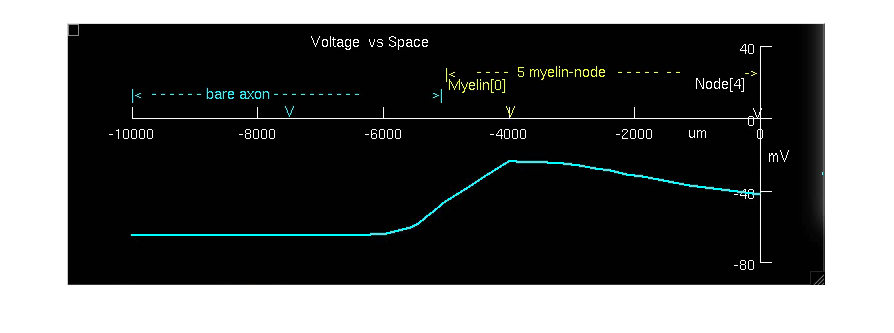

currSecondFrame = imcomplement(activeGif.cdata(:,:,:,activeSecondFrameIndex));

figure(2)
clf
imshow(currSecondFrame)

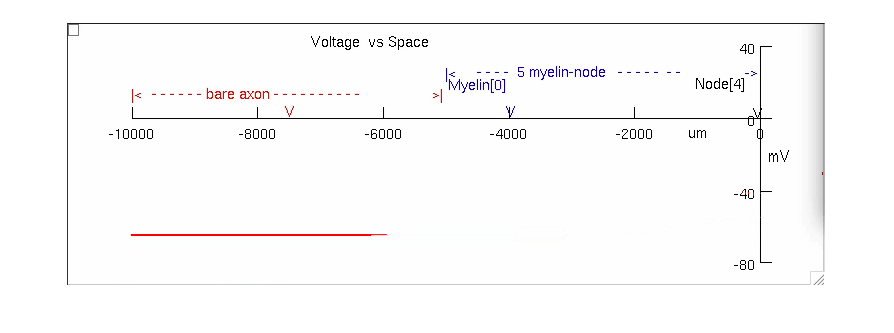

%imshow(currFrame, activeGif.colormap)

% Take pointwise maximum of each one?

[frameResult] = FnRemoveChangingObjects(currFrame, currSecondFrame);
figure(4)
clf
imshow(frameResult)

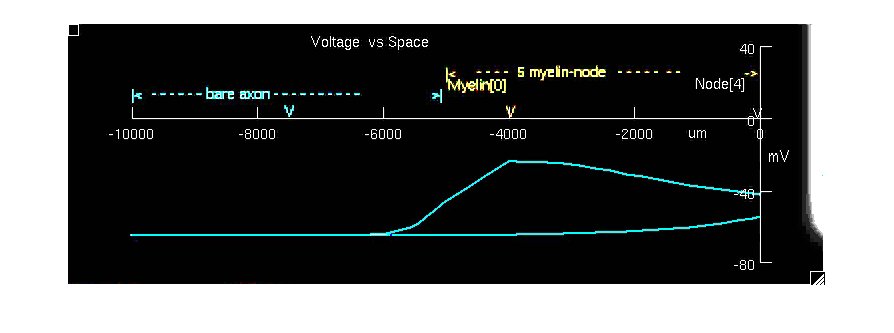



modifiedFrame = currSecondFrame .* currFrame;
figure(3)
clf
imshow(modifiedFrame)

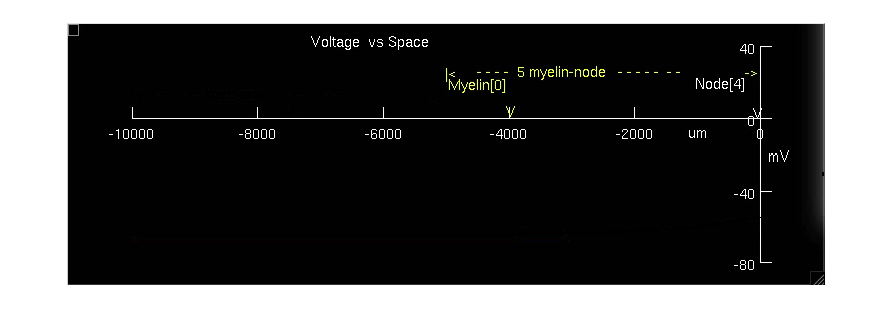

% 
% figure(1)
% clf

% Get main frame:
currFrame = activeGif.cdata(:,:,:,1);
currInvertedFrame = imcomplement(currFrame);	
[fixedImage, axesOnlyImage, excludedPixelsMask] = removeWhiteAxes(currInvertedFrame);
% axesOnlyMap = ~excludedPixelsMask;
% axesOnlyImage = currFrame(axesOnlyMap,:);

% Compute the "empty" color channels:



imshow(axesOnlyImage)

% When done, take the combinedFrame to be the blue channel of the data:
finalOutputPic = axesOnlyImage; % Start with axes image:

use_color_version = true;

color_map = jet(numberOfFrames);

color_map =                          0                         0         0.571428571428571
                         0                         0         0.714285714285714
                         0                         0         0.857142857142857
                         0                         0                         1
                         0         0.142857142857143                         1
                         0         0.285714285714286                         1
                         0         0.428571428571429                         1
                         0         0.571428571428571                         1
                         0         0.714285714285714                         1
                         0         0.857142857142857                         1


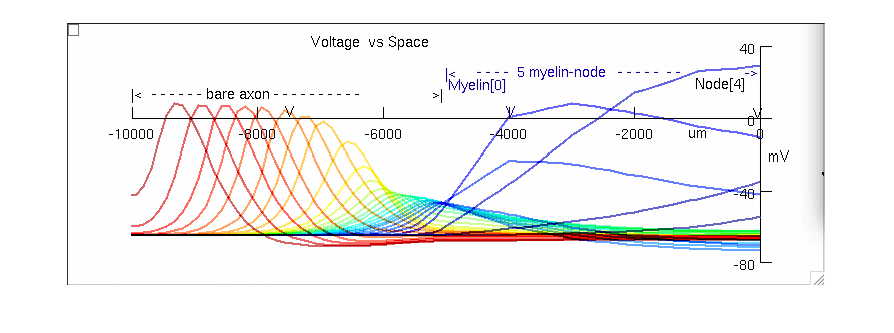

per_frame_opacity = 255/numberOfFrames;

for i=1:numberOfFrames
	currFrame = activeGif.cdata(:,:,:,i);
	currInvertedFrame = imcomplement(currFrame);
	
	% Binarize the image:
	[fixedImage, ~, excludedPixelsMask] = removeWhiteAxes(currInvertedFrame);
	fixedImage_grey = rgb2gray(fixedImage);
	fixedImage_BW = imbinarize(fixedImage_grey);

	if use_color_version
% 		curr_color = color_map(i,:);
		curr_inv_color = color_map(i,:);
		curr_color = ([1 1 1]- curr_inv_color);
		
		curr_flat_image = uint8(fixedImage_BW)*255*0.6;
		
		weighted_image(:,:,1) = curr_flat_image .* curr_color(1); % Multiply by red component of current color
		weighted_image(:,:,2) = curr_flat_image .* curr_color(2); % Multiply by green component of current color
		weighted_image(:,:,3) = curr_flat_image .* curr_color(3); % Multiply by blue component of current color
		
	else
		weighted_image = uint8(fixedImage_BW .* (i * per_frame_opacity));
	end	

	if i == 1
		if use_color_version
			combinedFrame = weighted_image;
		else
			combinedFrame = uint8(weighted_image);
		end	
	
	else
		% Should work for both versions
		combinedFrame = combinedFrame + weighted_image;
	end
end


if use_color_version
	finalOutputPic = finalOutputPic + combinedFrame;
else
	finalOutputPic(:,:,2) = finalOutputPic(:,:,2) + combinedFrame; %Add plots to the red channel
	finalOutputPic(:,:,3) = finalOutputPic(:,:,3) + combinedFrame; %Add plots to the red channel
end


% Invert to get back to original pic:
finalOutputPic = imcomplement(finalOutputPic);	

figure(2)
clf
% imshow(combinedFrame)
imshow(finalOutputPic)


imwrite(finalOutputPic, outputName);

function [dataOnlyImage, axesOnlyImage, excludedPixelsMask] = removeWhiteAxes(originalImage)
	% excludedPixelsMask: includes everywhere except for the plotted lines
	height = size(originalImage,1);
	width = size(originalImage,2);
	color_depth = size(originalImage,3);
	
	tolerance = 5;
	
% 	axesPixelsMask = logical(zeros([height, width]));
	excludedPixelsMask = logical(zeros([height, width]));
	dataOnlyImage = originalImage; % Initially copy the originalImage to the fixedImage
	axesOnlyImage = originalImage; % Initially copy the originalImage to the fixedImage
	
	
	for i = 1:height
		for j = 1:width
			% Loop through all pixels of the image:
			
			% Test if the pixel is white/grey/black:
			%% TODO: could also use the HSV curve's saturation value right?
			curr_RGB_pixel = originalImage(i,j,:);
			% They're white/gray/black if all color components are approximately
			% equal.
			curr_RGB_pixel_diff = curr_RGB_pixel - curr_RGB_pixel(1); % Subtract the first component away from all three, see if they're outside that range.
			curr_is_outside_tolerance = false;
			
			if abs(curr_RGB_pixel_diff(2)) < tolerance
				curr_is_outside_tolerance = true;
			elseif abs(curr_RGB_pixel_diff(3)) < tolerance
				curr_is_outside_tolerance = true;
			else
				curr_is_outside_tolerance = false;
			end
			
			if curr_is_outside_tolerance
				excludedPixelsMask(i,j) = true; % Set the mask to indicate that this is an excluded value.
				dataOnlyImage(i,j,:) = [0, 0, 0]; % Set it to pure black.
			else
				%For white/grey/black pixels, enable them.
				axesOnlyImage(i,j,:) = [0, 0, 0]; % Set it to pure black for all channels
			end
		end
	end
end